# P1. Dinámica Longitudinal del Vehículo

Sistemas de Control de Vehículos

Grado en Ingeniería Electrónica, Robótica y Mecátronica

Universidad de Málaga

Creado por: David Rodríguez Martínez

Última actualización: 18 Septiembre 2026

### Introducción y objetivos

Este archivo contiene a su vez el guión de la práctica y los bloques de código a completar. En esta primera práctica definiremos las propiedades, los parámetros de diseño de nuestro monoplaza de competición FSDriverless y diseñaremos el primer modelo dinámica longitudinal. 

Para completar esta práctica se necesita conocer la ecuación fundamental de movimiento longitudinal de un vehículo desarrollada en el Bloque 2. 

Al terminar esta práctica deberás ser capaz de:

- Escribir y simular la ecuación de movimiento longitudinal de un vehículo.

- Cerrar un lazo sencillo de control de velocidad. 

- Reconocer la estructura de simulación que reutilizaremos y ampliaremos en las siguientes prácticas.

🚧 **Importante**: *este es el primer bloque de tu proyecto individual. El archivo que completes hoy se convertirá en la base longitudinal del simulador del sistema de control de tu monoplaza que utilizarás durante todo el curso. Guárdalo. *

#### Qué vas a implementar

A) La aceleración longitudinal (función `pasoLongitudinal`)

B) La ley de control PI saturada (función `controlLongitudinal`)

### Parametros del vehículo

💡 **Tip**: *Vamos a utilizar un *`struct`* (o estructura). En Matlab las estructuras son un tipo de datos que agrupa información relacionada mediante contenedores llamados campos. Cada campo puede almacenar cualquier tipo de dato (números, texto, vectores, u otras matrices).* 

p = struct(); 
p.m = 230; % masa [kg]
p.g = 9.81; % gravedad
p.rho = 1.225; % densidad del aire [kg/m^3]
p.Cd = 1.0; % aerodinámica
p.Af = 1.1; % área frontal [m^2]
p.fr = 0.022; % rodadura
p.Fx_trac_max = 2500; % fuerza motriz máxima [N]
p.Fx_fren_max = 5000; % fuerza de frenado máxima [N]
p.theta = 0; % inclinación de la calzada [rad]

🧠 **Recordatorio**: la fuerza motriz máxima viene definida por el límite de adherencia del neumático y el límite de potencia/par del tren motriz. En el caso de la fuerza de frenado máxima, esta suele estar igualmente limitada por la adherencia pero con la ventaja del frenado de las cuatro ruedas (frente a un tracción trasera), lo que permite aprovechar el 100% de la masa del vehículo y la carga aerodinámica disponible.

### Modelo del vehículo

Aquí se debe definir la física del movimiento del vehículo en sentido longitudinal. Más adelante esta sección incluirá el modelo de nuestro vehículo al completo. 

Dada la posición del vehículo y la fuerza tractiva aplicada, deberemos calcular dónde se encuentra el vehículo en el siguiente paso temporal:

% Integración de la dinámica longitudinal
z0 = [0;0]; % z: vector de estados del vehículo [x; v_x]

function z_next = pasoLongitudinal(z, u, p, dt)
    Fx = u; 
    vx = z(2);

    % Resistencias
    Ra = 0.5*p.rho*p.Cd*p.Af*vx^2; % resistencia aerodinámica
    Rr = p.fr*p.m*p.g*cos(p.theta); % rodadura
    Rg = p.m*p.g*sin(p.theta); % gravitatoria

    % Aceleración 
    ax = (Fx - Ra - sign(vx)*Rr - Rg)/p.m;

    % Velocidad
    vx_next = max(vx + ax*dt,0); % velocidad en el siguiente instante de tiempo
    x_next = z(1)+vx*dt; 
    z_next = z;
    z_next(1) = x_next; 
    z_next(2) = vx_next; 
end

### Controlador velocidad 

Vamos a definir aquí nuestro controlador de velocidad en base al siguiente diagrama:

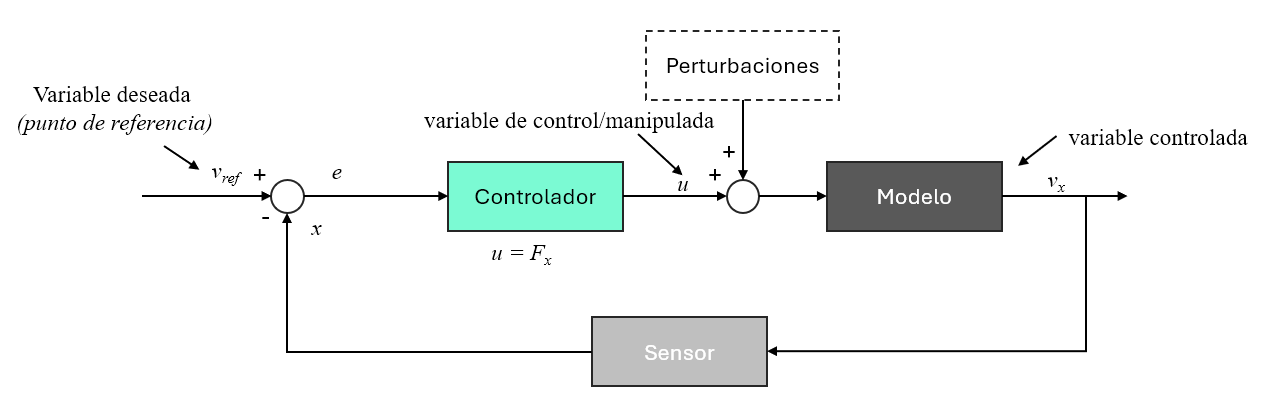

#### Recordatorio sobre controladores PI

Vamos a implementar un controlador PI de velocidad. Queremos que $v_x$ siga una referencia $v_{ref}$. El error, por tanto, vendrá definido por 


$$e = v_{ref} - v_x$$


y pedimos una fuerza de tracción proporcional a este error mas un termino integral que elimina el error en regimen permanente:


$$F_x = K_p \cdot e + K_i \int{e \cdot dt}$$


La fuerza real que se puede ejercer estará limitada por la adherencia y la capacidad de nuestro motor. $F_x
$ saturará entre máximo de frenado y el máximo de aceleración. 

**🧠Recordatorio**: *La saturación de un controlador ocurre cuando la señal de salida que calcula el controlador supera los límites físicos, eléctricos o de software del actuador que debe ejecutar la orden.*

💡*¿Por qué fuerza de tracción como variable de control? *Esta es una decisión que facilita la integración con la ecuación que gobierna el movimiento longitudinal. Es una manera de abstraer todo el tren de potencia (real) colapsándolo en una sola variable. En la realidad necesitaríamos modelar todo el tren de potencia (pedal del acelerador → par motor → fuerza tractiva) utilizando los mapas proprios del motor (no lineales para motores de combustion interna). 

% Controlador PI de velocidad
ctrl.v_cru = 40; % velocidad de crucero objetivo [m/s] (90 km/h)
ctrl.x_fren = 190; % distancia a la que se ordena frenar [m]
ctrl.Kp = 800; % ganancia proporcional 
ctrl.Ki = 200; % ganancia integral 

function [Fx, e_int] = controlLongitudinal(v_ref, vx, e_int, dt, ctrl, p)
    e = v_ref - vx; 
    % integral del error
    e_int = e_int + e*dt;
    Fx = ctrl.Kp*e + ctrl.Ki*e_int; % CONTROLADOR PI

    % Límites de saturación de mi controlador
    Fx = min(max(Fx, -p.Fx_fren_max), p.Fx_trac_max); %entre -5000N de frenada y 2500N de aceleración
end

### Geometría del circuito de pruebas

Vamos a simular una aceleración máxima durante 75 m seguida de una frenada en caja que deberá completarse en menos de 25 m (límite máximo de frenada a los 100 m). 

p.x_meta = 140;     % línea de cronometraje [m]
p.x_box  = 200;    % final de la caja de frenada [m]

%% SIMULADOR DE PRUEBA ACELERACIÓN Y FRENADA [NO MODIFICAR]
function [hist, t_evento] = simularE1(z0, p, ctrl, dt, Tmax)
    N = round(Tmax/dt);
    z = z0;
    hist.t  = zeros(1,N); hist.x  = zeros(1,N); hist.vx = zeros(1,N);
    hist.Fx = zeros(1,N); hist.vr = zeros(1,N);
    e_int = 0;  cruzada = false;  t_evento = NaN;  k_fin = N;
    for k = 1:N
        t = (k-1)*dt;
        if z(1) < ctrl.x_fren,  v_ref = ctrl.v_cru;  else,  v_ref = 0;  end
        [Fx, e_int] = controlLongitudinal(v_ref, z(2), e_int, dt, ctrl, p);
        z = pasoLongitudinal(z, Fx, p, dt);   % mando u = [Fx; delta]; delta = 0 en L1
        hist.t(k)=t; hist.x(k)=z(1); hist.vx(k)=z(2); hist.Fx(k)=Fx; hist.vr(k)=v_ref;
        if ~cruzada && z(1) >= p.x_meta,  cruzada = true;  t_evento = t;  end
        if cruzada && z(2) <= 0.05,  k_fin = k;  break;  end
    end
    f = 1:k_fin;
    hist.t=hist.t(f); hist.x=hist.x(f); hist.vx=hist.vx(f);
    hist.Fx=hist.Fx(f); hist.vr=hist.vr(f);
end

### Simulación

dt   = 0.005;
Tmax = 20; 

[hist, t_evento] = simularE1(z0, p, ctrl, dt, Tmax);

### Resultados 

**Qué esperar**: Deberíamos observar como el monoplaza acelera desde parado hasta la velocidad de crucero establecida (90 km/h) y la mantiene hasa cruzar la linea de 75m donde hemos establecido el comienzo de la frenada. Tras cruzar esta línea frena y se detiene dentro de la caja (antes de 100 m aprox).

fprintf('E1 — cruza %.0f m en  t = %.2f s\n', p.x_meta, t_evento);

E1 — cruza 140 m en  t = 5.48 s


fprintf('     se detiene en  X = %.1f m  (t = %.2f s)\n', hist.x(end), hist.t(end));

     se detiene en  X = 260.6 m  (t = 20.00 s)


fprintf('     v_max = %.1f m/s = %.0f km/h\n', max(hist.vx), max(hist.vx)*3.6);

     v_max = 49.5 m/s = 178 km/h


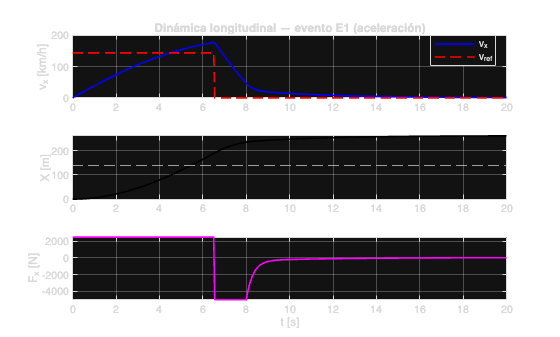

figure('Name','L1 · E1 — resultados','Color','w');
subplot(3,1,1);
  plot(hist.t, hist.vx*3.6,'b', hist.t, hist.vr*3.6,'r--','LineWidth',1.2);
  ylabel('v_x [km/h]'); grid on; legend('v_x','v_{ref}','Location','best');
  title('Dinámica longitudinal — evento E1 (aceleración)');
subplot(3,1,2);
  plot(hist.t, hist.x,'k','LineWidth',1.2); yline(p.x_meta,'--');
  ylabel('X [m]'); grid on;
subplot(3,1,3);
  plot(hist.t, hist.Fx,'m','LineWidth',1.2);
  ylabel('F_x [N]'); xlabel('t [s]'); grid on;

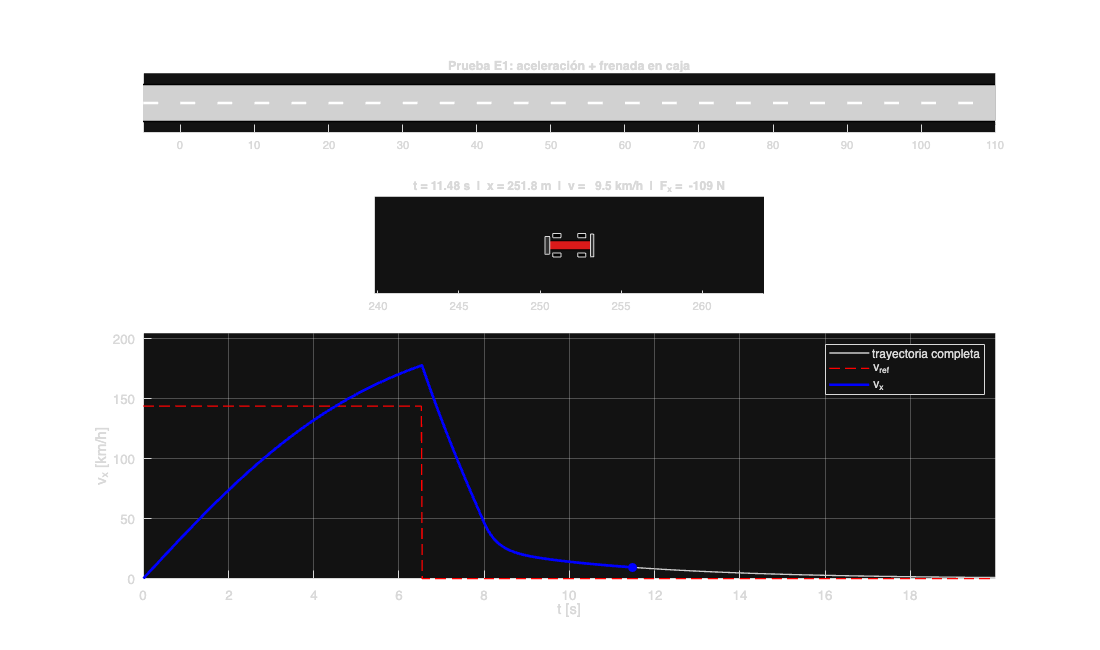

%% ANIMACIÓN DEL MONOPLAZA EN LA RECTA (prueba E1)
% Pegar en una sección NUEVA al final del Live Script, después de "Simulación".
% Usa las variables que ya existen: hist, p, ctrl, t_evento

% ---------- Ajustes ----------
vel_rep    = 1;      % 1 = tiempo real, 2 = doble de rápido, 0.5 = cámara lenta
fps        = 30;     % fotogramas por segundo
guardarGIF = false;  % true para guardar la animación como GIF
nombreGIF  = 'E1_aceleracion.gif';

% ---------- Fotogramas a dibujar ----------
dt_sim = hist.t(2) - hist.t(1);
salto  = max(1, round(vel_rep/(fps*dt_sim)));     % pasos de simulación por fotograma
idx    = unique([1:salto:numel(hist.t), numel(hist.t)]);

% ---------- Geometría del coche (vista en planta, metros) ----------
Lb  = 1.53;              % batalla (ld + lt de la P2)
via = 1.2;               % ancho de vía
rect = @(cx, cy, l, w) deal(cx + [-l l l -l]/2, cy + [-w -w w w]/2);   % rectángulo centrado

% ---------- Figura ----------
fig = figure('Name','Animación E1','Color','w','Position',[80 80 1100 650]);
ax1 = subplot(4,1,1);        % vista general de la recta
ax2 = subplot(4,1,2);        % cámara que sigue al coche
ax3 = subplot(4,1,[3 4]);    % velocidad en el tiempo
tf  = gobjects(1,2);  cuerpo = gobjects(1,2);
ejes = [ax1 ax2];

for i = 1:2
    a = ejes(i);  hold(a,'on');  axis(a,'equal');  a.YTick = [];
    % asfalto, caja de frenada y marcas en el suelo
    fill(a,[-20 125 125 -20],[-2.5 -2.5 2.5 2.5],[0.82 0.82 0.82],'EdgeColor','none');
    fill(a,[p.x_meta p.x_box p.x_box p.x_meta],[-2.5 -2.5 2.5 2.5],[1 0.88 0.55],'EdgeColor','none');
    for xm = -20:5:120
        plot(a,[xm xm+2],[0 0],'w-','LineWidth',2);           % línea discontinua central
    end
    plot(a,[-20 125],[ 2.5  2.5],'k-','LineWidth',1);
    plot(a,[-20 125],[-2.5 -2.5],'k-','LineWidth',1);
    plot(a,[p.x_meta p.x_meta],[-2.5 2.5],'k-','LineWidth',2);         % meta
    plot(a,[ctrl.x_fren ctrl.x_fren],[-2.5 2.5],'r--','LineWidth',1.5); % orden de frenada
    plot(a,[p.x_box p.x_box],[-2.5 2.5],'k-','LineWidth',4);           % final de la caja

    % coche: todas las piezas cuelgan de un hgtransform y se mueven juntas
    tf(i) = hgtransform('Parent',a);
    [xr,yr] = rect(0,0,2.6,0.55);       cuerpo(i) = patch('Parent',tf(i),'XData',xr,'YData',yr,'FaceColor',[0.5 0.5 0.5],'EdgeColor','k');
    [xr,yr] = rect( 1.40,0,0.20,1.40);  patch('Parent',tf(i),'XData',xr,'YData',yr,'FaceColor',[0.2 0.2 0.2]);   % alerón delantero
    [xr,yr] = rect(-1.35,0,0.30,1.10);  patch('Parent',tf(i),'XData',xr,'YData',yr,'FaceColor',[0.2 0.2 0.2]);   % alerón trasero
    for cx = [Lb/2 -Lb/2]
        for cy = [via/2 -via/2]
            [xr,yr] = rect(cx,cy,0.50,0.25);  patch('Parent',tf(i),'XData',xr,'YData',yr,'FaceColor','k');      % ruedas
        end
    end
end

xlim(ax1,[-5 110]);  ylim(ax1,[-4 4]);
text(ax1,p.x_meta,3.4,'meta 75 m','HorizontalAlignment','right');
text(ax1,ctrl.x_fren,-3.4,'frena 78 m','HorizontalAlignment','left','Color','r');
text(ax1,p.x_box,3.4,'fin caja 100 m','HorizontalAlignment','center');
title(ax1,'Prueba E1: aceleración + frenada en caja');
ylim(ax2,[-3 3]);

% gráfica de velocidad: curva completa en gris + trazo animado encima
hold(ax3,'on');  grid(ax3,'on');
plot(ax3,hist.t,hist.vx*3.6,'Color',[0.8 0.8 0.8],'LineWidth',1);
plot(ax3,hist.t,hist.vr*3.6,'r--','LineWidth',1);
lineaV = plot(ax3,hist.t(1),hist.vx(1)*3.6,'b','LineWidth',2);
puntoV = plot(ax3,hist.t(1),hist.vx(1)*3.6,'bo','MarkerFaceColor','b');
xlabel(ax3,'t [s]');  ylabel(ax3,'v_x [km/h]');
legend(ax3,{'trayectoria completa','v_{ref}','v_x'},'Location','northeast');
xlim(ax3,[0 hist.t(end)]);  ylim(ax3,[0 1.15*max(hist.vx*3.6)]);

% ---------- Bucle de animación ----------
t0 = tic;
for n = 1:numel(idx)
    k = idx(n);
    xk = hist.x(k);

    set(tf,'Matrix',makehgtform('translate',[xk 0 0]));   % mueve el coche en las dos vistas
    xlim(ax2,[xk-12 xk+12]);                              % la cámara sigue al coche

    % color según lo que hace el controlador
    if hist.Fx(k) > 50,      col = [0.10 0.70 0.20];      % verde: tracción
    elseif hist.Fx(k) < -50, col = [0.85 0.10 0.10];      % rojo: frenada
    else,                    col = [0.50 0.50 0.50];      % gris: casi sin fuerza
    end
    set(cuerpo,'FaceColor',col);

    title(ax2,sprintf('t = %5.2f s  |  x = %5.1f m  |  v = %5.1f km/h  |  F_x = %+5.0f N', ...
          hist.t(k), xk, hist.vx(k)*3.6, hist.Fx(k)));
    set(lineaV,'XData',hist.t(1:k),'YData',hist.vx(1:k)*3.6);
    set(puntoV,'XData',hist.t(k),'YData',hist.vx(k)*3.6);
    drawnow;

    if guardarGIF
        [A,map] = rgb2ind(frame2im(getframe(fig)),256);
        if n == 1
            imwrite(A,map,nombreGIF,'gif','LoopCount',Inf,'DelayTime',1/fps);
        else
            imwrite(A,map,nombreGIF,'gif','WriteMode','append','DelayTime',1/fps);
        end
    else
        pause(max(0, hist.t(k)/vel_rep - toc(t0)));       % sincroniza con el tiempo real
    end
end


fprintf('Cruza la meta en %.2f s | se detiene en X = %.1f m | v_max = %.0f km/h\n', ...
        t_evento, hist.x(end), max(hist.vx)*3.6);

Cruza la meta en 5.48 s | se detiene en X = 260.6 m | v_max = 178 km/h
